## Vehicle with 4 degrees of freedom


$$x_{t+1} =x_t +{hv}_t +{Gw}_t$$


Here, we expand the model from the vehicle on the track, so that we have a position and a velocity in the y-direction. This means the Jacobian definition has to be changed so that it has a y component, similar to the vehicle on the circle.


$$x_{t+1} =\left\lbrack \begin{array}{cccc}
1 & ht & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & ht\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


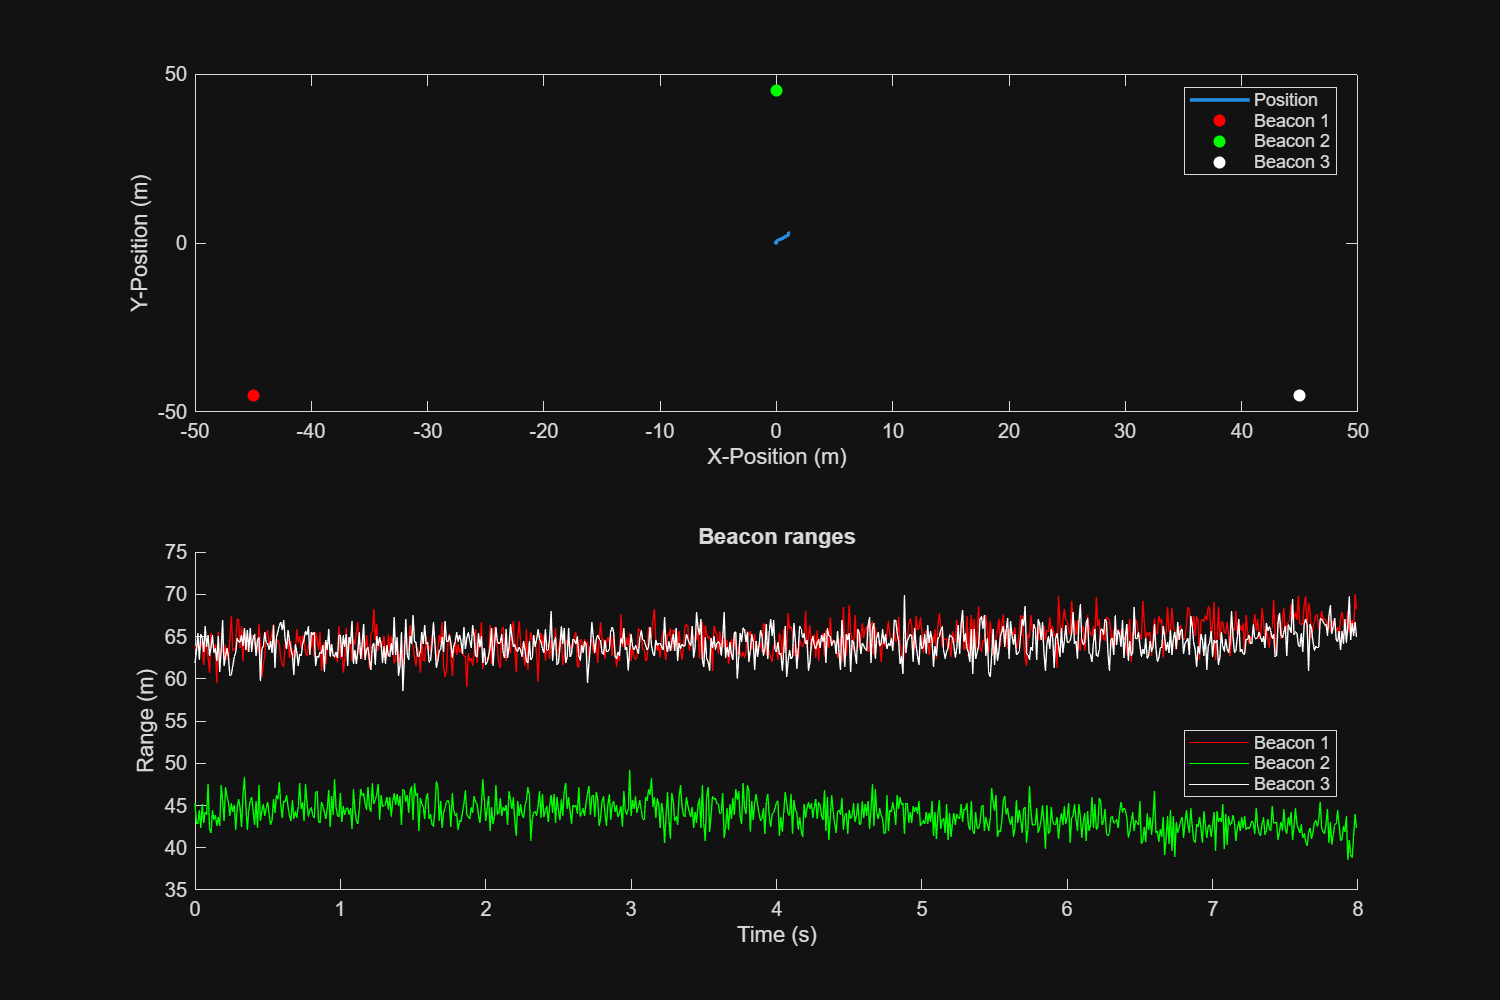

% Make sure to add Casadi to path and import it.
import casadi.*

% Setup.
fs = 100;
ht = 1/fs;

% State transition matrix.
A = [1 ht 0 0;
     0 1 0 0;
     0 0 1 ht;
     0 0 0 1];

% Noise variance for velocity, no position variance.
v_std = 1.5;

Q = [v_std^2 0;
     0 v_std^2];

G = [0 0;
     ht 0;
     0 0;
     0 ht];

% Define where the beacons are on the track. These are triangular around
% the track. If we change the locations, this will provide worse estimates.
beaconLocations = [-45 0 45; -45 45 -45]';
nBeacons = length(beaconLocations);

% Jacobian set up.
% Variable.
x = MX.sym('x', 4);

% Range to each beacon, loop over the function for each beacon.
h = MX.zeros(nBeacons, 1);
for i = 1 : nBeacons
    h(i) = sqrt((x(1) - beaconLocations(i, 1)) ^ 2 + (x(3) - beaconLocations(i, 2)) ^ 2);
end

% Jacobian here.
jh = jacobian(h, x);
Jhx = Function('h', {x}, {h});
Jh = Function('Jh', {x}, {jh});

% Measurement noise.
mu = zeros(1, nBeacons);
r = 1.5;
R = r^2 * eye(nBeacons);

% Initialisation.
nSamples = 800;
timeVector = (0 : nSamples) * ht;
stateVector = zeros(4, nSamples + 1);

% Need x and y co-ordinates.
measurementVector = zeros(nBeacons, nSamples);

% Initialisation
stateVector(:, 1) = [0 0 0 0]';

for t = 1 : nSamples

    % Noise for the velocity.
    processNoise = mvnrnd([0 0], Q)';

    % Note that there's no input terms here. They're in the script for
    % testing, but omitted because the model doesn't call for it.
    stateVector(:, t + 1) = A * stateVector(:, t) + G*processNoise;
    
    trackPosition = [stateVector(1, t) stateVector(3, t)];

    % Euclidean distance of the current position to each beacon location.
    distFromBeacons = vecnorm(trackPosition - beaconLocations, 2, 2);

    % Actual noise model provided.
    measurementNoise = mvnrnd(mu, R)';

    % Final measurement.
    measurementVector(:, t) =  distFromBeacons + measurementNoise;

end

f = figure;
f.Position = [0 0 1200 800];
tiledlayout(2, 1)
nexttile
plot(stateVector(1, :), stateVector(3, :), 'LineWidth', 1.8, 'DisplayName', 'Position')
hold on

beaconColours = {[1 0 0], [0 1 0], [1 1 1]};
for i = 1 : nBeacons
    scatter(beaconLocations(i, 1), beaconLocations(i, 2), ...
            'o', 'filled', 'MarkerFaceColor', beaconColours{i}, ...
        'DisplayName', "Beacon " + string(i))
end
xlabel('X-Position (m)')
ylabel('Y-Position (m)')
legend('Location', 'best')

nexttile
hold on
for i = 1 : nBeacons
    plot(timeVector(1 : end - 1), measurementVector(i, :), ...
        "Color", beaconColours{i}, 'DisplayName', ...
        "Beacon " + string(i))
end
xlabel('Time (s)')
ylabel('Range (m)')
title('Beacon ranges')
legend('Location', 'Best')

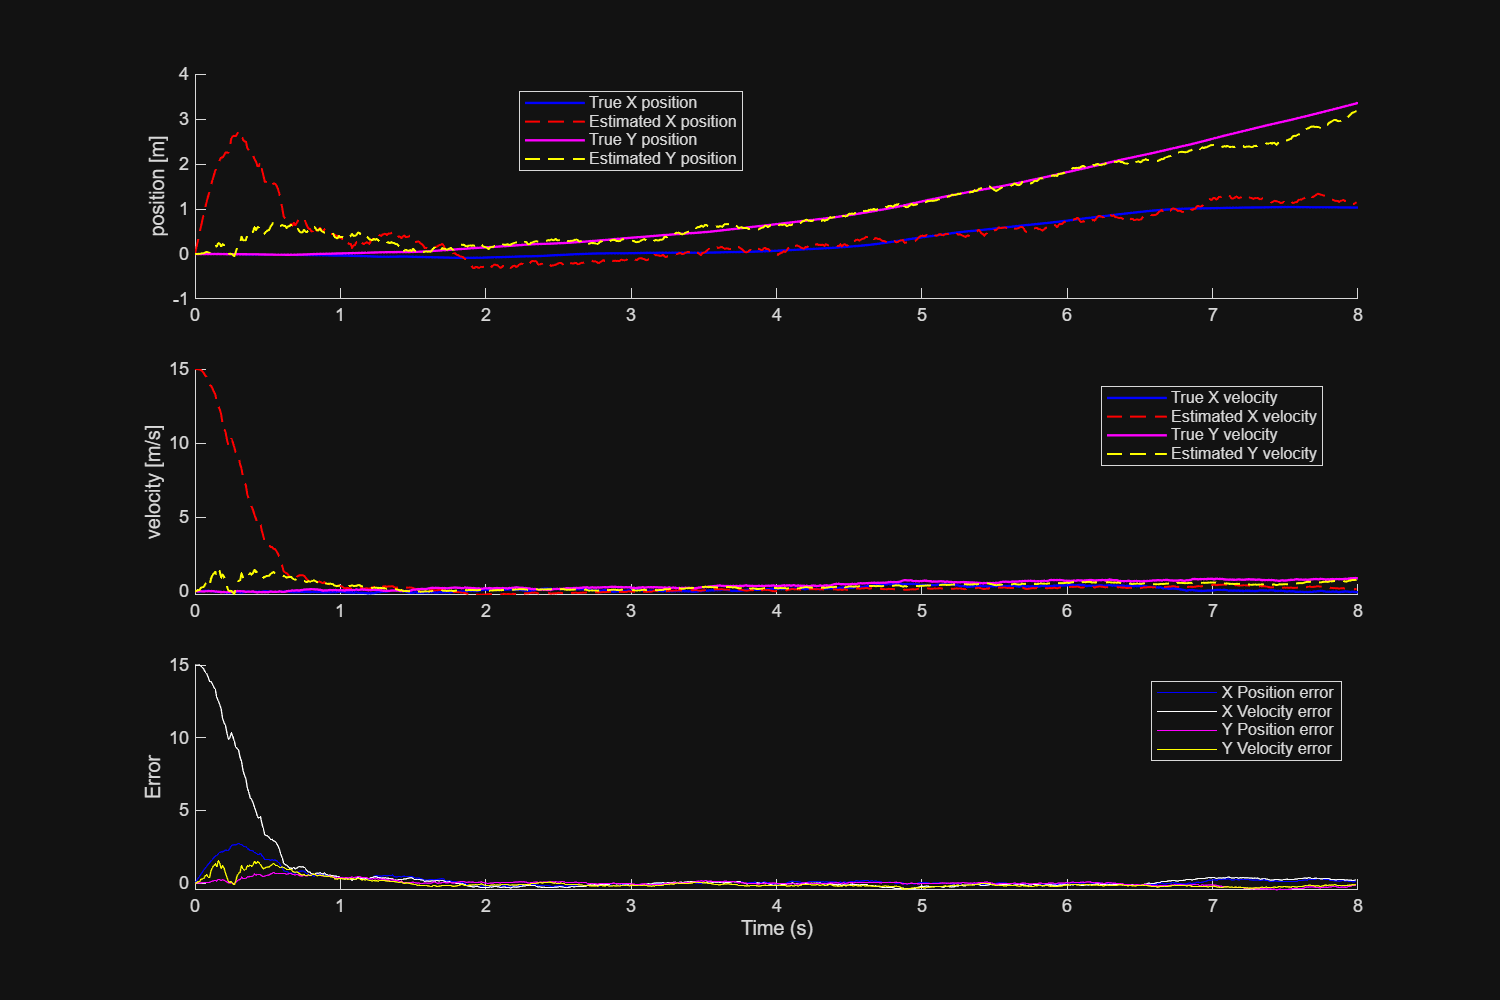

% Initialise these.
x_mu = zeros(4, nSamples);
sigma_mu = cell(1, nSamples);

% Initial estimate. Needs to be small for convergence.
x_tu = [0; 15; 0; 0];
sigma_tu = diag([0, v_std^2, 0, v_std^2]);

for k = 1 : nSamples
    % Jacobian steps to compute before Kalman Filter.
    h_x = full(Jhx(x_tu));
    C_lin = full(Jh(x_tu));
 
    % Keep a log of sigma and the estimated state. Measurement update.
    [sigma_mu{:, k}, x_mu(:, k)] = measurementUpdate(sigma_tu, x_tu, ...
        measurementVector(:, k), C_lin, R, h_x);

    % Time update step.
    [sigma_tu, x_tu] = timeUpdate(sigma_mu{:, k}, x_mu(:, k), A, Q, G);

end

f = figure;
f.Position = [0 0 1200 800];
tiledlayout(3, 1)

% Plots.
nexttile
hold on;
plot(timeVector, stateVector(1,:), 'b', 'LineWidth', 1.2, 'DisplayName', 'True X position')
plot(timeVector(1 : end - 1), x_mu(1,:), 'r--', 'LineWidth', 1, 'DisplayName', 'Estimated X position')
plot(timeVector, stateVector(3,:), 'm', 'LineWidth', 1.2, 'DisplayName', 'True Y position')
plot(timeVector(1 : end - 1), x_mu(3,:), 'y--', 'LineWidth', 1, 'DisplayName', 'Estimated Y position')
ylabel('position [m]');
legend('Location','best')

nexttile
hold on;
plot(timeVector, stateVector(2,:), 'b', 'LineWidth', 1.2, 'DisplayName', 'True X velocity')
plot(timeVector(1 : end - 1), x_mu(2,:), 'r--', 'LineWidth', 1, 'DisplayName', 'Estimated X velocity')
plot(timeVector, stateVector(4,:), 'm', 'LineWidth', 1.2, 'DisplayName', 'True Y velocity')
plot(timeVector(1 : end - 1), x_mu(4,:), 'y--', 'LineWidth', 1, 'DisplayName', 'Estimated Y velocity')
ylabel('velocity [m/s]')
legend('Location','best')

nexttile
hold on
XPositionError = x_mu(1,:) - stateVector(1, 1 : end - 1);
XVelocityError = x_mu(2,:) - stateVector(2, 1 : end - 1);
YPositionError = x_mu(3,:) - stateVector(3, 1 : end - 1);
YVelocityError = x_mu(4,:) - stateVector(4, 1 : end - 1);
plot(timeVector(1 : end - 1), XPositionError, 'b', 'DisplayName', 'X Position error')
plot(timeVector(1 : end - 1), XVelocityError, 'w', 'DisplayName', 'X Velocity error')
plot(timeVector(1 : end - 1), YPositionError, 'm', 'DisplayName', 'Y Position error')
plot(timeVector(1 : end - 1), YVelocityError, 'y', 'DisplayName', 'Y Velocity error')
ylabel('Error')
xlabel('Time (s)')
legend

Position estimation is so good here because we have 3 beacons. If we take out one of the beacons, it becomes worse. If we only have 1 beacon, the estimator doesn't know which side the beacon is on.

Bare in mind this is only in one dimension, if we bump it up to 2 dimensions, the effect will be exacerbated due to circumferential geometry.

function [sigma, x] = measurementUpdate(sigma, x, y, C, R, h_x)
    z = C * sigma * C' + R;
    x = x + sigma * C' * linsolve(z, y - h_x);
    sigma = sigma - sigma * C' * linsolve(z, C * sigma);
end

function [sigma, x] = timeUpdate(sigma, x, A, Q, G)
    x = A * x;
    sigma = A * sigma * A' + G * Q * G';
end
